## Atomic Force Microscopy

### 1. Importing the force curves

Make a copy of the main.mlx live script and the src directory and paste it to the directory where the force curve files are. The first step assumes that the force curves files are in the same directory as this script. 

This will create the standard directory layout:

`./raw: `Where the jpk-force files are

`./incoming: `Where the relevant channels will be extracted to.

`./processed: `Where the shift-scaled force curves will be safed

And extract  a *filename*_approach.mat and a *filename_*retract.mat matrix, in which the first column is the respective sensor height and the second column the deflection.

Remember to correctly set the path after opening this script.

 
clear;
fullScriptPath = matlab.desktop.editor.getActiveFilename;
[script_dir, ~, ~] = fileparts(fullScriptPath);
% Change directory to the live script's directory
cd(script_dir);
addpath('./src/')

path_incoming = './incoming/';
path_processed = './processed/';
path_raw = './raw/';
if exist('./raw/',"dir")
    force_dir = dir(fullfile(path_raw,'*.jpk-force'));
else
    force_dir = dir(fullfile(script_dir,'*.jpk-force'));
end
num_curves=size(force_dir,1)

num_curves = 1008

 
if ~exist(path_incoming,"dir")
    mkdir(path_incoming)
end
if ~exist(path_processed,"dir")
    mkdir(path_processed)
end
if ~exist(path_raw,"dir")
    mkdir(path_raw)
end

force_dir = dir(fullfile(script_dir,'*.jpk-force'));
for i = 1:length(force_dir)
    base_str = force_dir(i).name;
    src_file = fullfile(script_dir, base_str);
    dest_file = fullfile(path_raw, base_str);
    
    try
        copyfile(src_file, dest_file);
        if exist(dest_file, 'file') == 2
            delete(src_file);
        else
            error('File copy failed: %s', base_str);
        end
    catch ME
        fprintf('Error occurred: %s. File was not deleted: %s\n', ME.message, base_str);
    end
end

force_dir = dir(fullfile(path_raw,'*.jpk-force'));
for i = 1:length(force_dir)
    base_str =force_dir(i).name;
    extract(path_raw,path_incoming,base_str,2);
end


### 2. Rescaling the force curves

The force curves need to be rescaled in order to get physical units. Two linear fits are to be made to achieve this. One for constant compliance and one for the baseline regions. First the respective intervals need to be chosen to get the best fit for all curves. 

Plot a few example force curves to chose the interval where the baseline and constant compliance is linear.

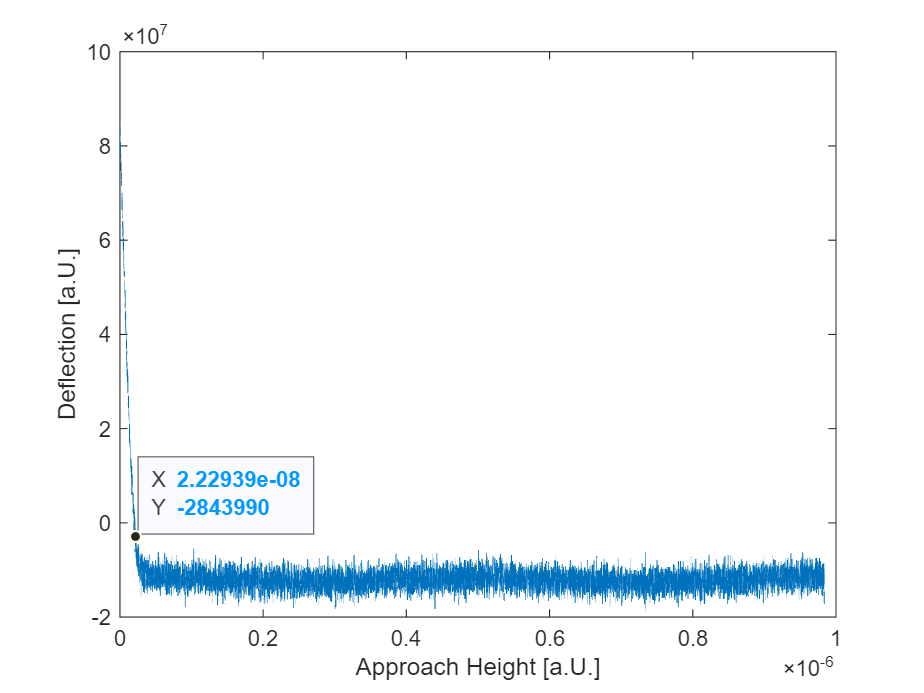

 
cd(script_dir);
curve_id =  687;
base_str = force_dir(curve_id).name;
load(fullfile(path_incoming,[base_str,'_approach.mat']))
plot(height,deflection)
xlabel('Approach Height [a.U.]');
ylabel('Deflection [a.U.]');

% Improved MATLAB code to load all approach and retract curves, overlay them, and save as PNG

% Directory containing your data files (replace with the correct path)

% Create a new figure
figure;

% Hold on to overlay all curves on the same figure
hold on;
% Loop through each curve_id in the directory
for curve_id = 1:length(force_dir)
    
    % Base string from the filename (assuming filenames are consistent)
    base_str = force_dir(curve_id).name;
    
    approach_file = fullfile(path_incoming, [base_str, '_approach.mat']);
    load(approach_file)
    plot(approach_height,approach_deflection, Color='blue')

    retract_file = fullfile(path_incoming, [base_str, '_retract.mat']);
    load(retract_file)
    plot(retract_height,retract_deflection, Color='red')
end

% Add labels and title
xlabel('Height [a.U.]');
ylabel('Deflection [a.U.]');
title('Overlayed Approach and Retract Force Curves');

% Customize the grid and axis
grid on;
axis tight;

% Save the figure as a PNG image
saveas(gcf, 'all_curves_overlay.png');

% Close the figure (optional)
close(gcf);


Then chose the Interval of constant compliance and of the baseline.  The distribution of the Sum of Squared Errors of the fits will be shown. *Should be gaussian and as low as possible?*. 

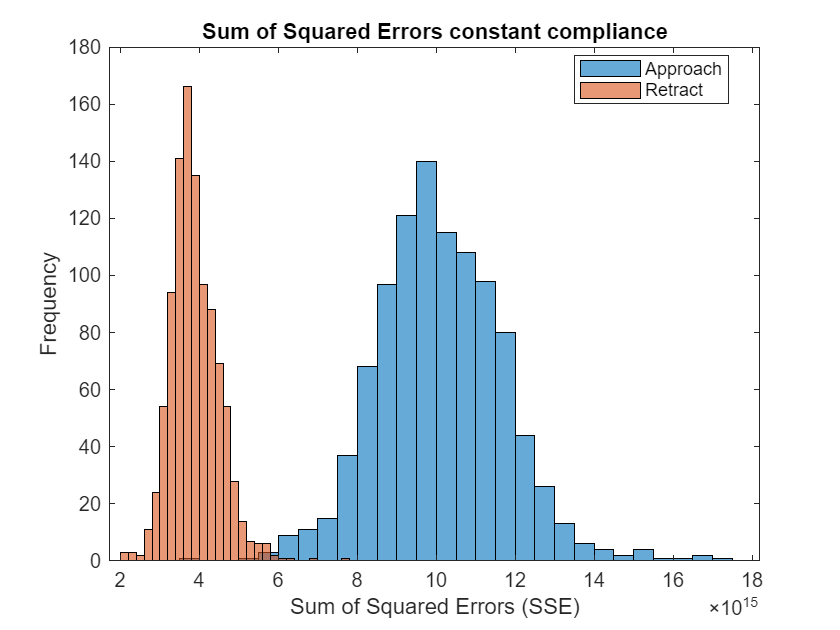

 
cd(script_dir)
%const_compliance_min = 0;
const_compliance_max = 2.2e-8;
baseline_min = 4e-7;
baseline_max = 0.000001;

n = length(force_dir);
SSEc = zeros(1, n);
mc = zeros(1, n);
bc = zeros(1, n);
SSE = zeros(1, n);
m = zeros(1, n);
b = zeros(1, n);

r_SSEc = zeros(1, n);
r_mc = zeros(1, n);
r_bc = zeros(1, n);
r_SSE = zeros(1, n);
r_m = zeros(1, n);
r_b = zeros(1, n);

for i =1:length(force_dir)
    base_str = force_dir(i).name;
    [SSEc(i),mc(i),bc(i), SSE(i), m(i), b(i)] = fitforce(path_incoming,[base_str,'_approach.mat'], const_compliance_max,baseline_min);%approach
    [r_SSEc(i),r_mc(i),r_bc(i), r_SSE(i), r_m(i), r_b(i)] = fitforce(path_incoming,[base_str,'_retract.mat'], const_compliance_max,baseline_min);%retract
end
figure;
histogram(SSEc, 'DisplayName', 'Approach')
hold on; 
histogram(r_SSEc, 'DisplayName', 'Retract')
xlabel('Sum of Squared Errors (SSE)'); 
ylabel('Frequency'); 
title('Sum of Squared Errors constant compliance');
legend('Location', 'best');
hold off;

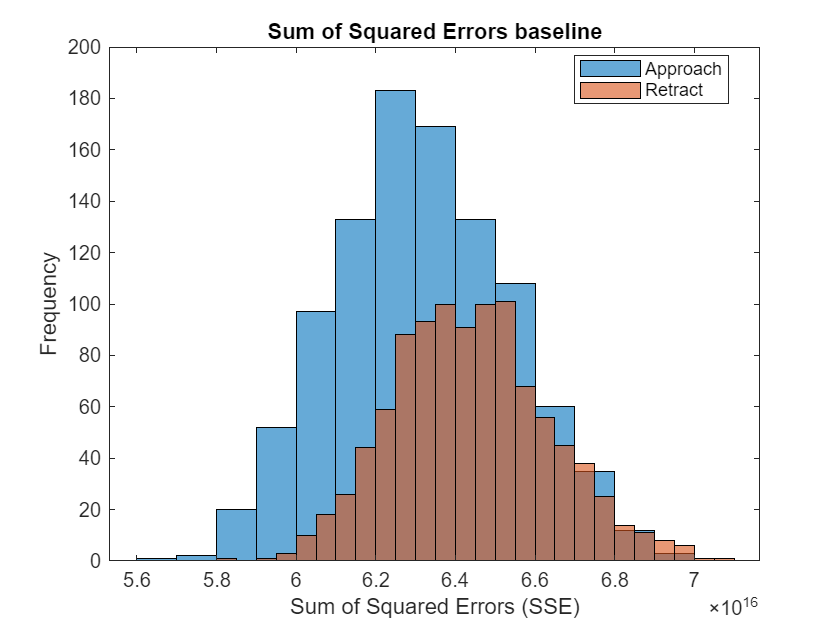


figure;
histogram(SSE,'DisplayName', 'Approach')
hold on;
histogram(r_SSE,'DisplayName', 'Retract');
xlabel('Sum of Squared Errors (SSE)');
ylabel('Frequency'); 
title('Sum of Squared Errors baseline');
legend('Location', 'best');
hold off;

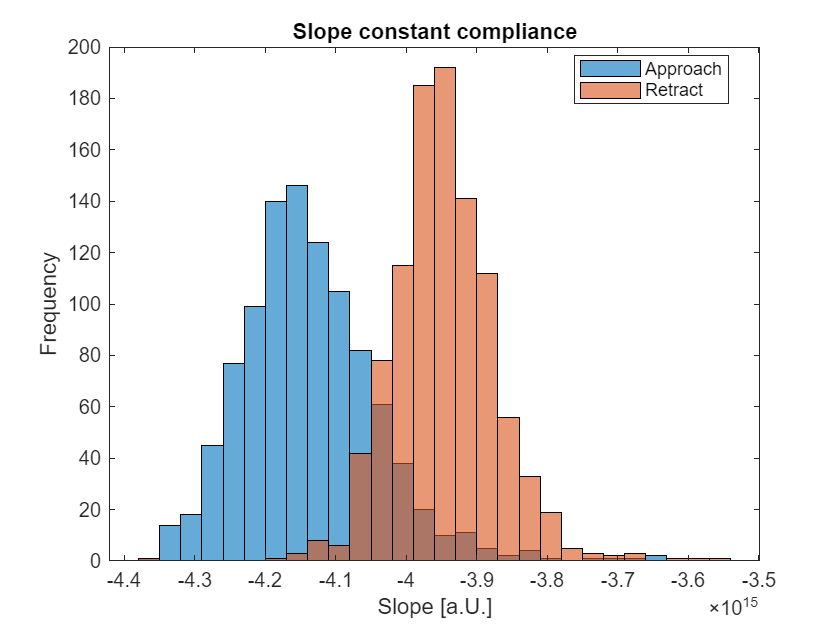

figure;
histogram(mc,'DisplayName', 'Approach')
hold on;
histogram(r_mc,'DisplayName', 'Retract')
xlabel('Slope [a.U.]');
ylabel('Frequency'); 
title('Slope constant compliance');
legend('Location', 'best');
hold off;

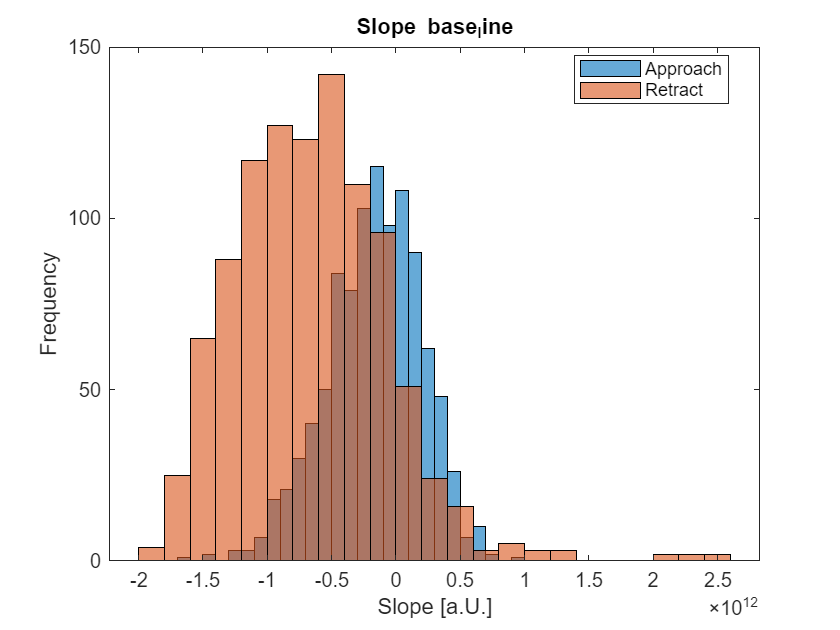

figure;
histogram(m,'DisplayName', 'Approach')
hold on; 
histogram(r_m,'DisplayName', 'Retract')
xlabel('Slope [a.U.]');
ylabel('Frequency'); 
title('Slope base_line');
legend('Location', 'best');
hold off;

You can again inspect the force curves with their fits.

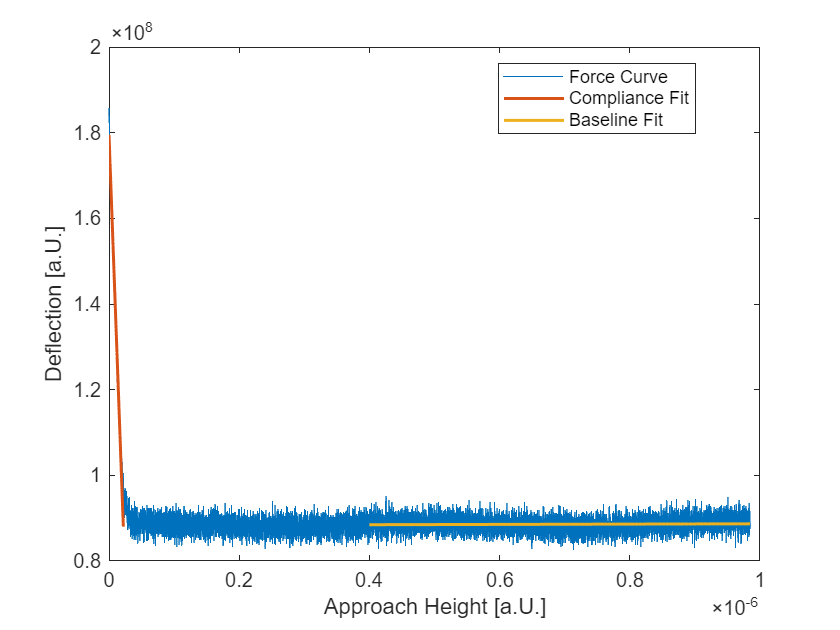

 
cd(script_dir);
curve_id =  438;
base_str = force_dir(curve_id).name;
approach=load(fullfile(path_incoming,[base_str,'_approach.mat']),'height','deflection');
retract=load(fullfile(path_incoming,[base_str,'_retract.mat']));
plot(approach.height,approach.deflection)
xlabel('Approach Height [a.U.]');
ylabel('Deflection [a.U.]');

hold on;

% Define the first line: left-most approach height to constant_compliance_max
x1 = linspace(0, const_compliance_max, 100); % Define the range
y1 = mc(curve_id) * x1 + bc(curve_id); % Calculate the y-values
plot(x1, y1, 'LineWidth', 1.5); % Plot with a dashed red line

% Define the second line: baseline_min to baseline_max
x2 = linspace(baseline_min, max(approach.height), 100); % Define the range
y2 = m(curve_id) * x2 + b(curve_id); % Calculate the y-values
plot(x2, y2, 'LineWidth', 1.5); % Plot with a dashed green line

% Add labels
xlabel('Approach Height [a.U.]');
ylabel('Deflection [a.U.]');

% Add a legend for clarity
legend('Force Curve', 'Compliance Fit', 'Baseline Fit', 'Location', 'Best');

hold off;

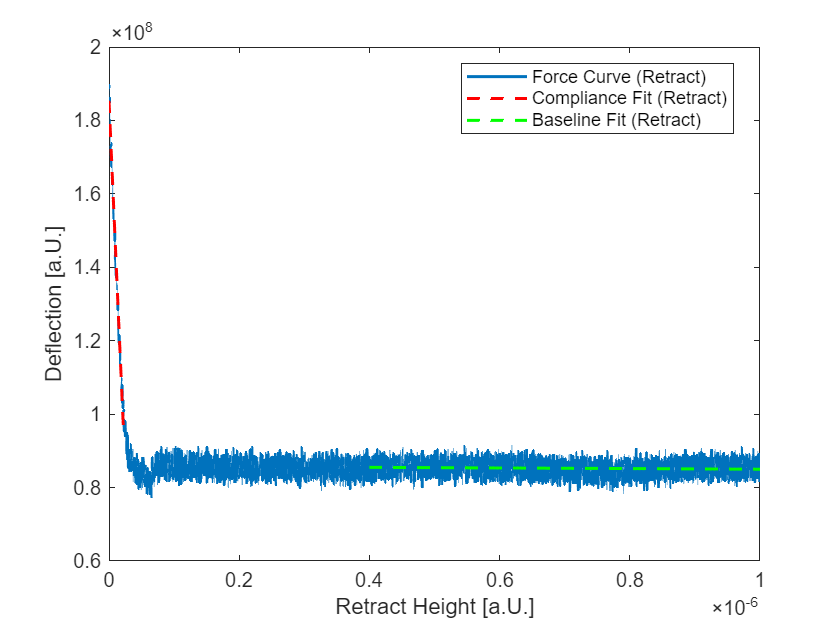

% Second figure: Retract data and fits
figure;
plot(retract.height, retract.deflection, 'LineWidth', 1.5); % Plot the retract data
xlabel('Retract Height [a.U.]');
ylabel('Deflection [a.U.]');
hold on;

% Compliance Fit for retract
x1_retract = linspace(0, const_compliance_max, 100); % Range
y1_retract = r_mc(curve_id) * x1_retract + r_bc(curve_id); % Compliance fit for retract
plot(x1_retract, y1_retract, '--r', 'LineWidth', 1.5); % Dashed red line for retract compliance

% Baseline Fit for retract
x2_retract = linspace(baseline_min, max(retract.height), 100); % Range
y2_retract = r_m(curve_id) * x2_retract + r_b(curve_id); % Baseline fit for retract
plot(x2_retract, y2_retract, '--g', 'LineWidth', 1.5); % Dashed green line for retract baseline

% Legend and finishing touches
legend('Force Curve (Retract)', 'Compliance Fit (Retract)', 'Baseline Fit (Retract)', 'Location', 'Best');
hold off;

Now the force curves will be rescaled to get physical units. Enter the cantilever spring constant k to get a force on the y axis.

 
cd(script_dir);
k =0.085176;
baseline_min_shifted = zeros(length(force_dir),1);
baseline_max_shifted = zeros(length(force_dir),1);
for i =1:length(force_dir)
    base_str = force_dir(i).name;
    rescale(path_incoming, path_processed, base_str, mc(i),bc(i),m(i),b(i), r_mc(i),r_bc(i),r_m(i),r_b(i),k)
    baseline_min_shifted(i) =baseline_min + (-bc(i)+ b(i))/(mc(i)-m(i));
    baseline_max_shifted(i) =baseline_max + (-bc(i)+ b(i))/(mc(i)-m(i));
end


You can plot a few scaled example curves. 

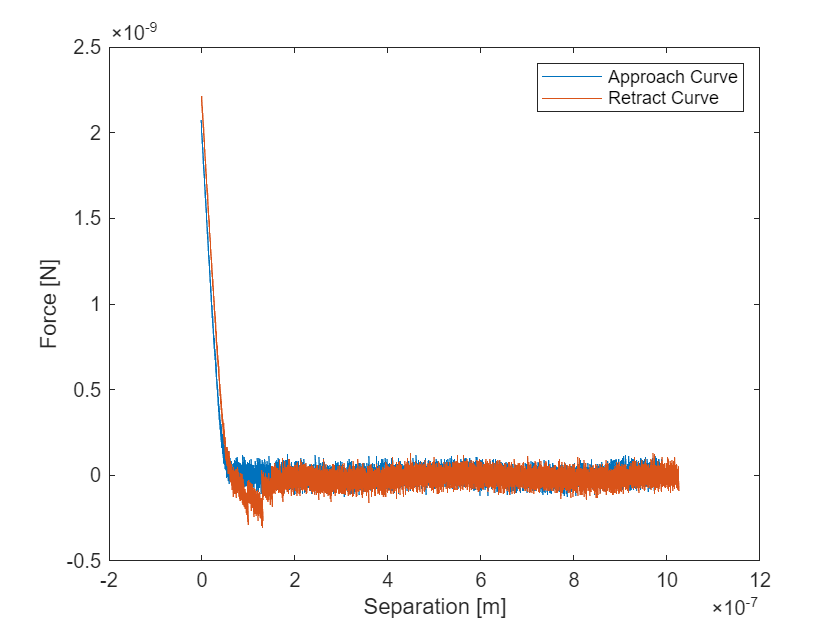

 
cd(script_dir);
curve_id =  430;
base_str = force_dir(curve_id).name;
approach = load(fullfile(path_processed,[base_str,'_approach_scaled.mat']));
retract = load(fullfile(path_processed,[base_str,'_retract_scaled.mat']));

% Plot the approach curve
plot(approach.shifted_height, approach.scaled_deflection, 'DisplayName', 'Approach Curve');
hold on;
% Plot the retract curve
plot(retract.shifted_height, retract.scaled_deflection, 'DisplayName', 'Retract Curve');
% Add labels
xlabel('Separation [m]');
ylabel('Force [N]');
% Add a legend
legend('show'); % Automatically uses the 'DisplayName' properties of the plots
hold off;

### 3. Measuring the cantilever spring constant

Now the spring constant of the cantilever will be estimated using a Fourier Transformation of the baseline vibrations. Enter the approach velocity in m/s to convert the approach height to units of time. This can be omitted if it was measured on the Instrument.

 
velocity = 0.0000015;
cd(script_dir);
for i =1:length(force_dir)
    base_str = force_dir(i).name;
    Copy_of_powerspec(path_processed,base_str,velocity,baseline_min_shifted(i),baseline_max_shifted(i))
end


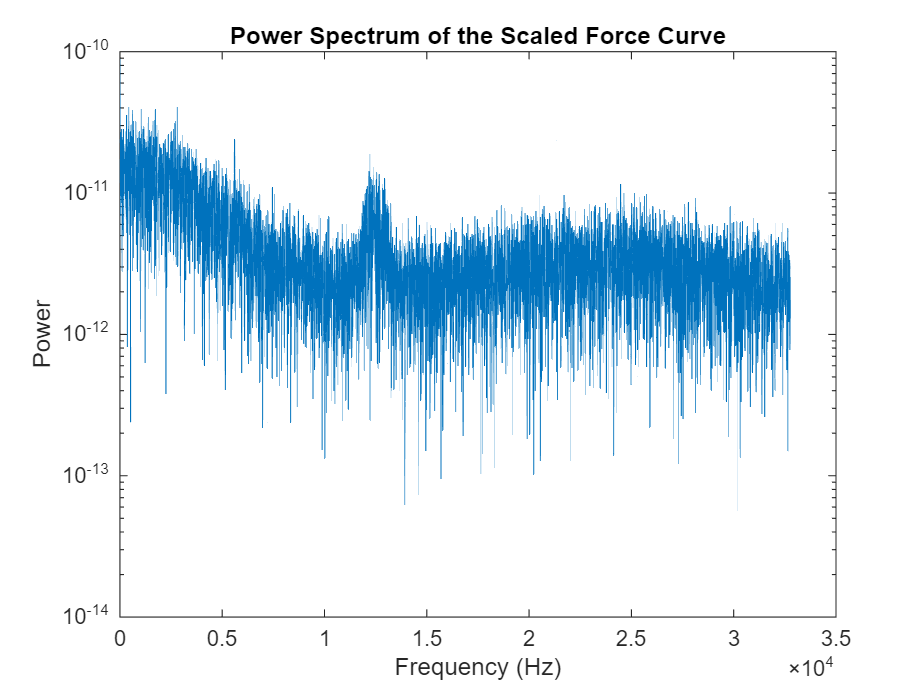

 
cd(script_dir)
curve_id =  93;
base_str = force_dir(curve_id).name;
load(fullfile(path_processed,[base_str,'_power_spectrum.mat']))
% Plot the power spectrum
figure;
semilogy(frequencies, power_spectrum);
xlabel('Frequency (Hz)');
ylabel('Power');
title('Power Spectrum of the Scaled Force Curve');

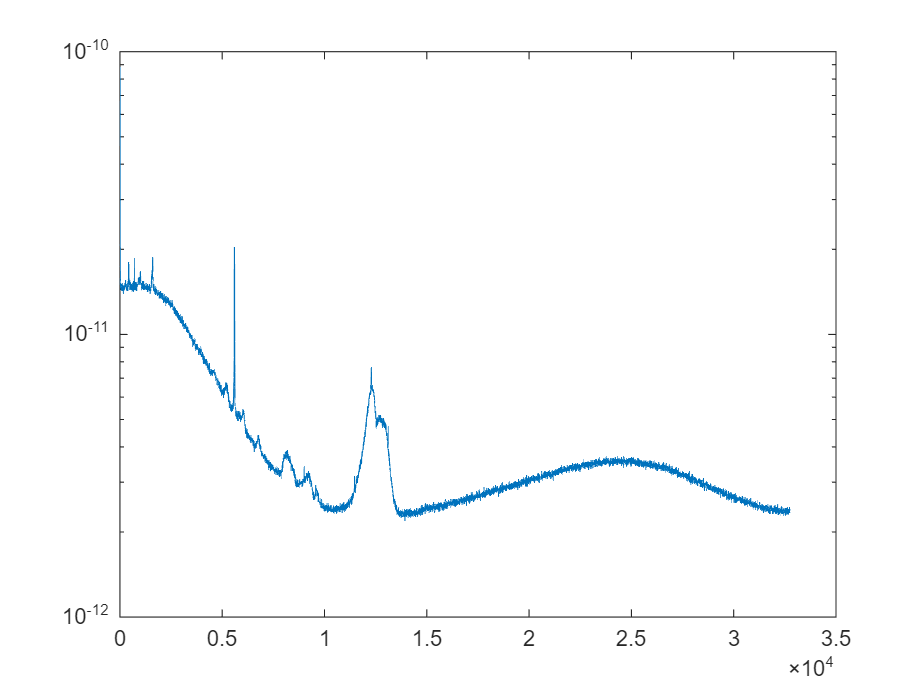

 
% Loading files
files = dir(fullfile(path_processed, '*power_spectrum.mat'));

% Initialize variables
num_spectra = length(files);
min_num_points = inf;  % Initialize to a large number

% First, loop through the files to find the common frequency range and the min number of points
for i = 1:num_spectra
    data = load(fullfile(path_processed, files(i).name));
    power_spectrum = data.power_spectrum;
    frequencies = data.frequencies;

    % Update the common frequency range (min and max across all files)
    if i == 1
        freq_min = min(frequencies);
        freq_max = max(frequencies);
    else
        freq_min = max(freq_min, min(frequencies));
        freq_max = min(freq_max, max(frequencies));
    end

    % Find the number of valid points within the common range
    valid_indices = find(frequencies >= freq_min & frequencies <= freq_max);
    num_valid_points = length(valid_indices);
    
    % Track the minimum number of valid points across all spectra
    min_num_points = min(min_num_points, num_valid_points);
end

% Calculate bin width based on the minimum number of data points
frequency_range = freq_max - freq_min;
bin_width = frequency_range / min_num_points;  % Dynamic bin width based on min number of points

% Define the common frequency bins based on the bin width
common_frequencies = freq_min:bin_width:freq_max;

% Initialize accumulated power
accumulated_power = zeros(length(common_frequencies)-1, 1);

% Loop through each spectrum and bin the power
for i = 1:num_spectra
    data = load(fullfile(path_processed, files(i).name));
    power_spectrum = data.power_spectrum;
    frequencies = data.frequencies;

    % Find the indices of frequencies that are within the common frequency range
    valid_indices = find(frequencies >= freq_min & frequencies <= freq_max);
    
    % Extract the valid frequencies and corresponding power spectrum values
    valid_frequencies = frequencies(valid_indices);
    valid_power_spectrum = power_spectrum(valid_indices);

    % Bin the power spectrum
    [~, bin_indices] = histc(valid_frequencies, common_frequencies);  % Get bin indices
    
    % Accumulate power in the corresponding bins
    for k = 1:length(valid_frequencies)
        if bin_indices(k) > 0 && bin_indices(k) <= length(accumulated_power)
            accumulated_power(bin_indices(k)) = accumulated_power(bin_indices(k)) + valid_power_spectrum(k);
        end
    end
end

% Compute the mean binned spectrum
mean_binned_spectrum = accumulated_power / num_spectra;

% Plot the result
semilogy(common_frequencies(1:end-1), mean_binned_spectrum);  % Exclude last bin edge for plot
saveas(gcf,"./thermal_noise_spectrum.png")

## Finding rupture events through clustering

#### Stephans greedy clustering:

Import part of the force curves in which a rupture event is expected. It is recommended to have a decent part of the baseline as well. n is the number of sampling points in the interval. min_height is the start and max_height the end of the interval used for clustering Try to exclude as much of the constant compliance as possible and use only as much baseline as needed to include the rupture events. The runtime scales quadratically with n and due to the curse of dimensionality distances will become less and less meaningless in high dimensional spaces. If chosen too low the rupture events will vanish in noise however.

 
cd(script_dir);

n = 2000;
min_height=5.1e-8;
max_height = 4e-7 ;
num_spectra = length(force_dir);

% First, loop through the files to find the common frequency range and the min number of points
tmpX_all = zeros(num_spectra,n);

for i = 1:num_spectra
    retract = load(fullfile(path_processed, [force_dir(i).name, '_retract_scaled.mat']));
    
    % Find valid indices where shifted_height is in the specified range
    valid_indices = find(retract.shifted_height <= max_height & retract.shifted_height >= min_height);
    num_valid = numel(valid_indices);  % Get the number of valid points

    if num_valid < n
        error('Not enough valid points to sample.');
    end

    % Select n evenly spaced indices from valid_indices
    sampled_indices = valid_indices(round(linspace(1, num_valid, n)));

    % Extract deflection values at sampled indices
    deflection = retract.scaled_deflection(sampled_indices, :);
    tmpX_all(i, :) = deflection;
end


tmpX_id_all = 1:num_spectra;

tmpX_all=tmpX_all';
tmpX_id_all=tmpX_id_all';

Calculate the distances of curves to another. Sort by the distances and then calculate the logarithmic distances, which will be used by the clustering algorithm

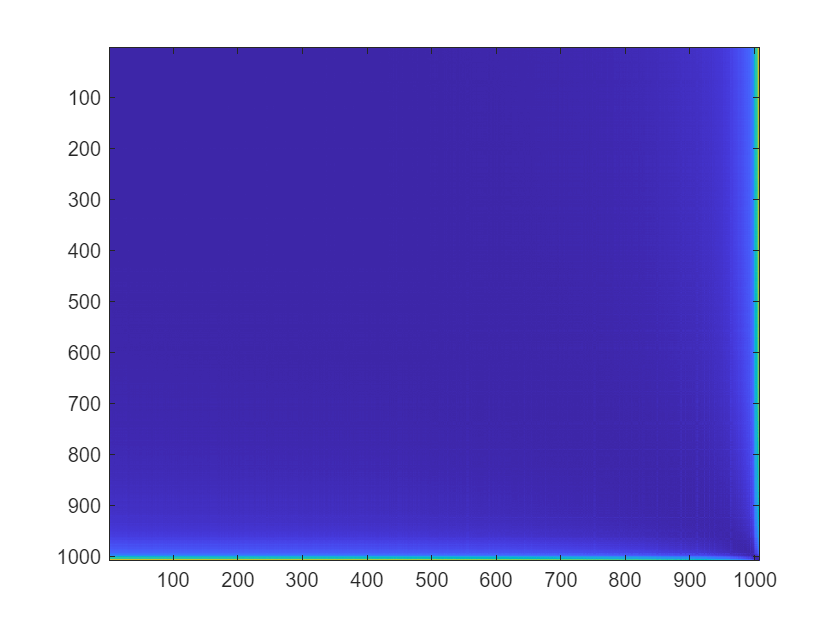

 
sd = pairdistances(tmpX_all);
tmptmp=median(sd,2);
[iy,ii]=sort(tmptmp);
sd = pairdistances(tmpX_all(:,ii));
sd2 = logdistances(tmpX_all,sd);
figure;
imagesc(sd2);

Cluster by the distances. Chose a threshold of similarity for clustering. Each time this button is clicked a new clustering iteration is started. Usually it works best to start with a low threshold and increase in every clustering iteration.

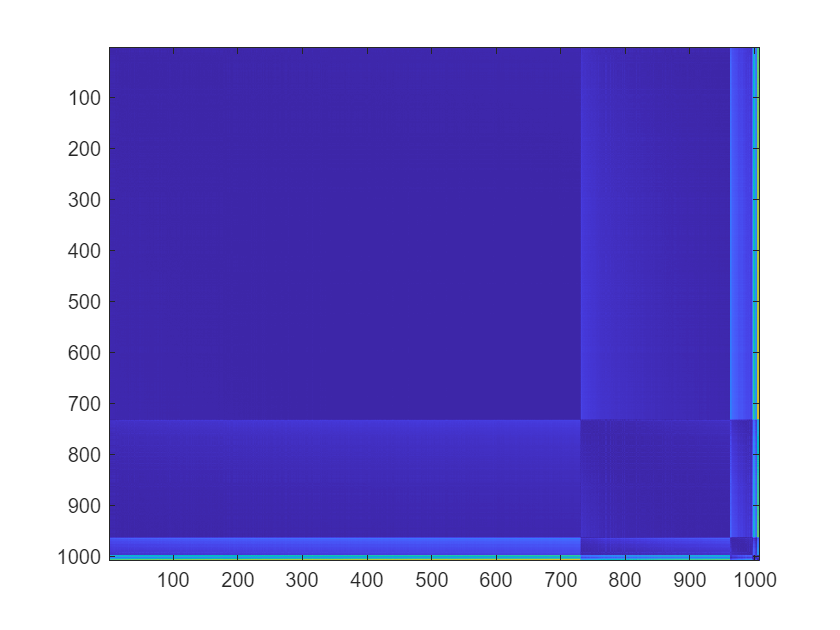

 
threshold= 0.2;
ii2=greedycluster(sd2,ii,threshold);

ii=ii2';
% %second iteration
sd = pairdistances(tmpX_all(:,ii));
sd2 = logdistances(tmpX_all(:,ii),sd);
figure;
imagesc(sd2);

has_event = false(1,length(tmpX_id_all));

Similar curves will be clustered. Typically rupture events can be found in the clusters with high distance to the rest of the curves (with just the baseline) on the right and left of the sd plot. You can plot the curves and assign whether a curve containts a rupture event. If a curve contains >= 1 rupture event you can select it by pressing switch selection. Pressing switch selection again will then in turn discard the curve. Once all curves with rupture events are selected press "Save Selection" to create a renamed copy of the selected force curves for reproducibility later on. If you wish to reset your selection and delete the renamed copies press "Reset".

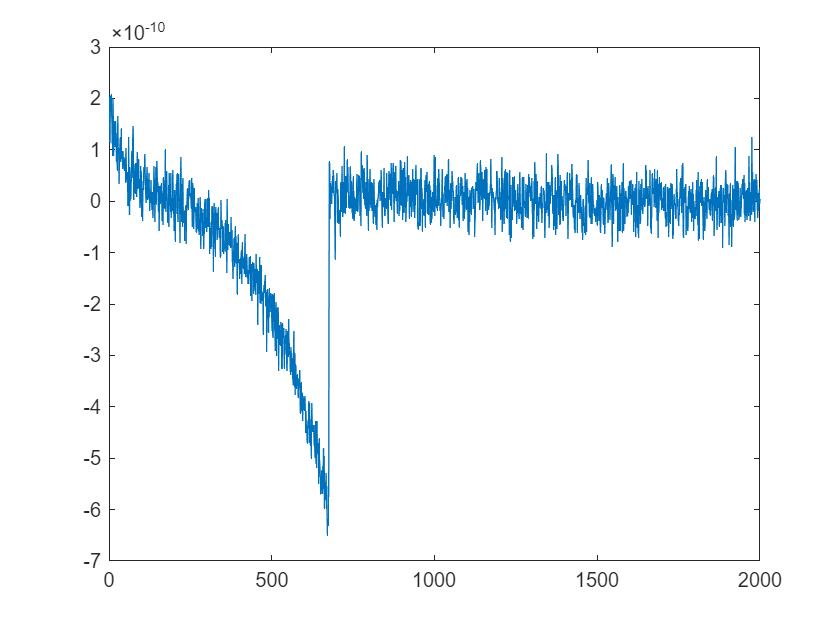

 
cd(script_dir);
curve_id =  769;
plot((1:size(tmpX_all,1)),tmpX_all(:,ii(curve_id)),'-','Tag',num2str(tmpX_id_all(ii(curve_id))));

if(has_event(curve_id))    
    display("ACCEPT: >= 1 rupture event.")
else
    display("DISCARD: No rupture events.")
end

    "DISCARD: No rupture events."



 
if(has_event(curve_id))
    has_event(curve_id)=false;
    display("The Curve will now be DISCARDED.")
else
    has_event(curve_id)=true;
    display("The curve will now be ACCEPTED.")
end

    "The curve will now be ACCEPTED."



Alternatively enter a range of curves with rupture events.

 
accept_min = 1;
accept_max =1008;
has_event(accept_min:accept_max) = true;
display(strcat("The curves from ",num2str(accept_min) ," to ", num2str(accept_max)," will be accepted."))

    "The curves from 1 to 1008 will be accepted."



 
cd(script_dir);
for i = 1:length(has_event)
    if has_event(i)
        % Get the original file name from force_dir using index ii(i)
        base_str = [force_dir(ii(i)).name,'_retract_scaled.mat'];
        % Create the new file name 
        new_file = [base_str, '_rupture.mat' ];
        % Define the full paths 
        originalFilePath = fullfile(path_processed, base_str);
        newFilePath      = fullfile(path_processed, new_file);
        % Make a copy of the file with the new name
        copyfile(originalFilePath, newFilePath);
    end
end
display("Curves with rupture events were copied.")

    "Curves with rupture events were copied."



 
cd(script_dir);
choice = questdlg(['Do you really want to reset? ' ...
    'All files with the extension *_rupture.mat in ' path_processed ' will be deleted.'], ...
    'Reset Confirmation', 'Yes', 'No', 'No');

% Process the user's choice.
if strcmp(choice, 'Yes')
    % Find all files that end with '_rupture.mat'
    ruptureFiles = dir(fullfile(path_processed, '*_rupture.mat'));
    has_event = false(1,length(tmpX_id_all));
    % Loop over each file and delete it.
    for k = 1:length(ruptureFiles)
        fileToDelete = fullfile(path_processed, ruptureFiles(k).name);
        delete(fileToDelete);
    end
    disp('Reset complete: All *_rupture.mat files have been deleted.');
else
    disp('Reset cancelled.');
end

Reset complete: All *_rupture.mat files have been deleted.


### Loading rate and rupture Force

### Loading rate and rupture Force

Introduce offset so that rupture is always negative? Remove velocity parameter.

cd(script_dir);
 
fit_mFJC_UI(path_processed);

Plot the rupture force vs the loading rate.

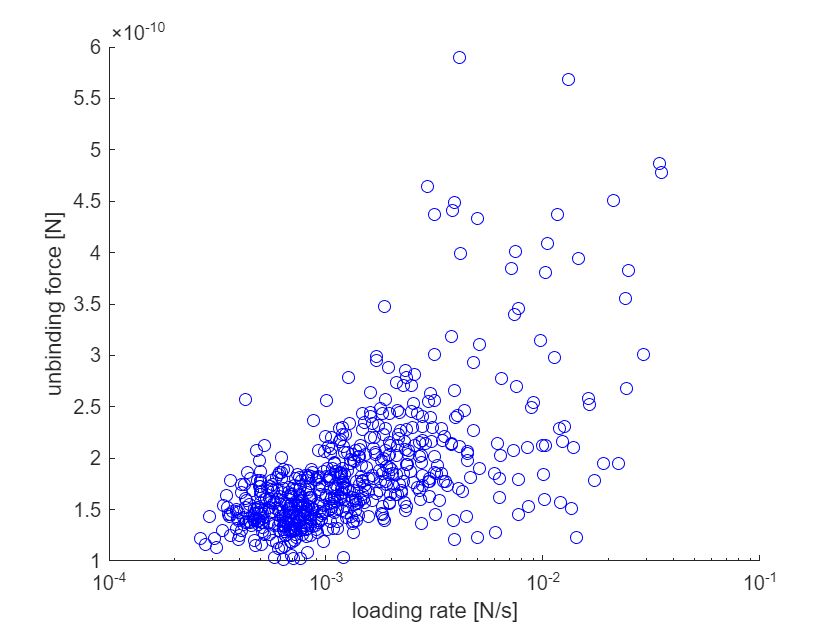

 
cd(script_dir);
fit_results = load(strcat(path_processed,'fitResults.mat')).fitResults;

loading_rate=zeros(1,size(fit_results,1));
unbinding_force=zeros(1,size(fit_results,1));
for i=1:size(fit_results,1)
    loading_rate(i)=-fit_results(i).loading_rate;
    unbinding_force(i)=-fit_results(i).unbinding_force;
end
figure;
scatter(loading_rate, unbinding_force,'MarkerEdgeColor', 'b')
set(gca, 'XScale', 'log')
xlabel('loading rate [N/s]')
ylabel( 'unbinding force [N]')

% hold off;

Optionally import data from other experiments, by selecting the directory of the other main script. For reproducibility it is recommended to add the paths as actual code.

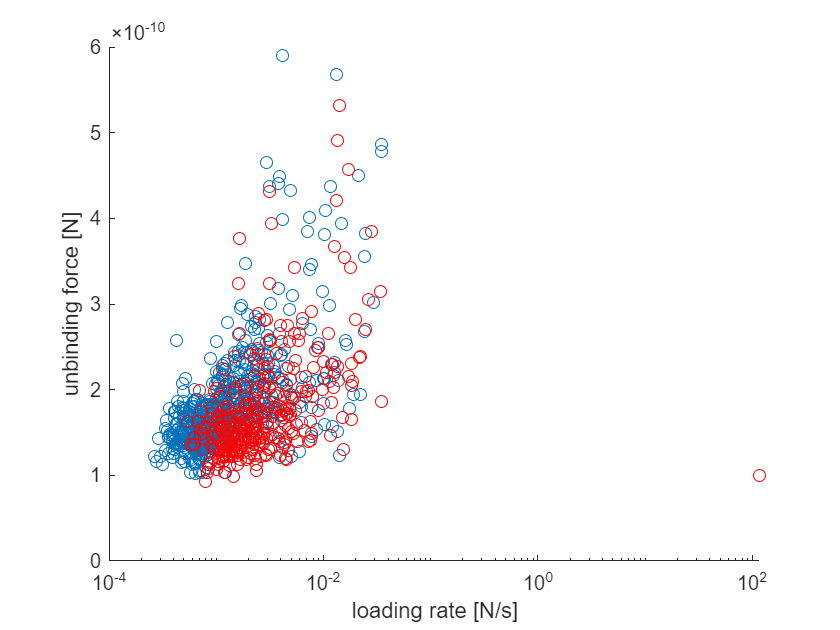

 
path = uigetdir();
cd(script_dir);
other = load(strcat(path,'/processed/','fitResults.mat')).fitResults;

figure; hold on;
 scatter(loading_rate,unbinding_force)
 for i=1:size(other,1)
     other_loading_rate(i)=-other(i).loading_rate;
     other_unbinding_force(i)=-other(i).unbinding_force;
 end
 scatter(other_loading_rate, other_unbinding_force,'MarkerEdgeColor', 'r')

set(gca, 'XScale', 'log')
xlabel('loading rate [N/s]')
ylabel( 'unbinding force [N]')
hold off;

loading_rate = [loading_rate other_loading_rate];
unbinding_force = [unbinding_force other_unbinding_force];

Bin into constant loading rates. Exclude outliers and set the bin size implicitly by chosing a  minimum number of elements per bin.

% PARAMETERS
 
minElements = 25;           % Minimum number of events per bin
max_allowed_rate = 2e-7;    % Global threshold for loading_rate (nN/s)
max_allowed_force =5e-10;  % Global threshold for unbinding_force (pN)

% --- Global filtering ---
% Identify valid data and outliers
valid_idx = (loading_rate <= max_allowed_rate) & (unbinding_force <= max_allowed_force);
outlier_idx = ~valid_idx;

% Filter data
rate_valid = loading_rate(valid_idx);
force_valid = unbinding_force(valid_idx);

rate_outliers = loading_rate(outlier_idx);
force_outliers = unbinding_force(outlier_idx);

% --- Plot raw data ---
figure;
% Plot valid data as light gray dots
scatter(rate_valid, force_valid, 10, [0.7 0.7 0.7], 'filled'); 
hold on
set(gca, 'XScale', 'log')

% Plot outliers as red crosses
scatter(rate_outliers, force_outliers, 30, 'rx', 'LineWidth',1.5);

% --- Sort the valid data by loading_rate ---
[sorted_rate, sortIdx] = sort(rate_valid);
sorted_force = force_valid(sortIdx);
numData = numel(sorted_rate);

% --- Preallocate vectors for binned statistics ---
numBins = floor(numData / minElements);
bin_avg_rate = zeros(numBins, 1);
bin_avg_force = zeros(numBins, 1);
bin_std_force = zeros(numBins, 1);

% --- Bin the valid data ---
for i = 1:numBins
    idx_start = (i-1)*minElements + 1;
    idx_end = i*minElements;
    
    bin_rates  = sorted_rate(idx_start:idx_end);
    bin_forces = sorted_force(idx_start:idx_end);
    
    % Compute average values for the bin
    bin_avg_rate(i) = mean(bin_rates);
    bin_avg_force(i) = mean(bin_forces);
    
    % Standard deviation of forces for error bars
    bin_std_force(i) = std(bin_forces);
end

% --- Plot binned averages with error bars ---
errorbar(bin_avg_rate, bin_avg_force, bin_std_force, 'bo', 'LineWidth', 1.5, ...
    'MarkerFaceColor','b');

% --- Formatting the plot ---
xlabel('Loading Rate (N/s)');
ylabel('Unbinding Force (N)');
grid on
hold off
tau = (pi/2.*bin_std_force).^1/2./bin_avg_rate;

A possibly more sophisticated approach than just binning is to chose the bins in a way that loading rate only varies with a predefined relative percentage. This accounts for the assumptions of constant loading rate. Pass the max_bin_fraction parameter to account for this relative width of the bins.

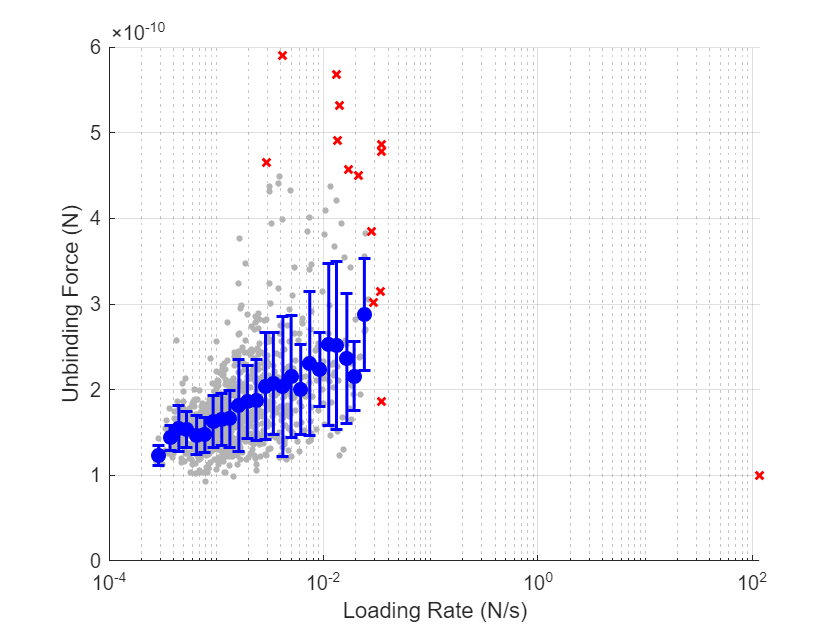

Binned average loading rates:
    0.0003    0.0004    0.0004    0.0005    0.0007    0.0008    0.0009    0.0011    0.0013    0.0016    0.0020    0.0024    0.0029    0.0034    0.0042    0.0050    0.0061    0.0075    0.0093    0.0112    0.0132    0.0165    0.0193    0.0241

Binned average unbinding forces:
   1.0e-09 *

    0.1233    0.1438    0.1543    0.1535    0.1470    0.1475    0.1624    0.1652    0.1661    0.1816    0.1856    0.1875    0.2042    0.2072    0.2035    0.2151    0.2004    0.2305    0.2237    0.2528    0.2512    0.2364    0.2157    0.2878



function [bin_avg_rate, bin_avg_force, bin_std_force] = customBinningRelative(loading_rate, unbinding_force, minElements, max_allowed_rate, max_allowed_force, max_bin_fraction)
    % --- Global filtering ---
    valid_idx = (loading_rate <= max_allowed_rate) & (unbinding_force <= max_allowed_force);
    outlier_idx = ~valid_idx;
    
    % Filter data based on global criteria
    rate_valid = loading_rate(valid_idx);
    force_valid = unbinding_force(valid_idx);

    rate_outliers = loading_rate(outlier_idx);
    force_outliers = unbinding_force(outlier_idx);
    
    % --- Sort valid data by loading_rate ---
    [sorted_rate, sortIdx] = sort(rate_valid);
    sorted_force = force_valid(sortIdx);
    numData = numel(sorted_rate);
    
    % --- Relative binning: grouping points with similar loading rates ---
    bin_avg_rate = [];
    bin_avg_force = [];
    bin_std_force = [];
    binned_indices = false(numData, 1);
    
    i = 1;
    while i <= numData
        % Reference loading rate for this bin:
        ref_rate = sorted_rate(i);
        % Define the maximum allowed loading rate in the bin (relative tolerance)
        max_rate = ref_rate * (1 + max_bin_fraction);
        j = i;
        while j <= numData && sorted_rate(j) <= max_rate
            j = j + 1;
        end
        
        % Candidate bin: indices from i to j-1
        candidate_indices = i:(j-1);
        if numel(candidate_indices) >= minElements
            % Accept the candidate bin and calculate statistics
            bin_avg_rate(end+1)  = mean(sorted_rate(candidate_indices));
            bin_avg_force(end+1) = mean(sorted_force(candidate_indices));
            bin_std_force(end+1) = std(sorted_force(candidate_indices));
            binned_indices(candidate_indices) = true;
            i = j; % move to the next unbinned data point
        else
            % Not enough points in the candidate bin: skip the current point
            i = i + 1;
        end
    end
    
    % --- Compute tau (average bond lifetime measure) for each valid bin ---
    % tau = variance / (mean^2)
   
    
    % --- Plotting the results ---
    figure;
    hold on;
    set(gca, 'XScale', 'log');

    % Plot the binned valid data as light gray dots.
    scatter(sorted_rate(binned_indices), sorted_force(binned_indices), 10, [0.7 0.7 0.7], 'filled');

    % Plot global outliers as red crosses.
    scatter(rate_outliers, force_outliers, 30, 'rx', 'LineWidth', 1.5);

    % Plot valid but unbinned points as red crosses.
    leftover_idx = ~binned_indices;
    scatter(sorted_rate(leftover_idx), sorted_force(leftover_idx), 30, 'rx', 'LineWidth', 1.5);
    
    % Plot binned averages with error bars using blue circles.
    errorbar(bin_avg_rate, bin_avg_force, bin_std_force, 'bo', 'LineWidth', 1.5, 'MarkerFaceColor', 'b');
    
    xlabel('Loading Rate (N/s)');
    ylabel('Unbinding Force (N)');
    grid on;
    hold off;
    
    % Optionally, display the resulting vectors in the command window:
    fprintf('Binned average loading rates:\n');
    disp(bin_avg_rate);
    
    fprintf('Binned average unbinding forces:\n');
    disp(bin_avg_force);
end


 
minElements = 4;           % Minimum number of events per bin
max_allowed_rate = 0.2;    % Global threshold for loading_rate (N/s)
max_allowed_force =4.5e-10;      % Global Threshold for force
max_bin_fraction =0.2;       % How much is the rate allowed the vary in a bin (relative)
[bin_avg_rate, bin_avg_force, bin_std_force]=customBinningRelative(loading_rate, unbinding_force, ...
                      minElements, max_allowed_rate, max_allowed_force, max_bin_fraction); 

 tau = sqrt(pi/2.*(bin_std_force.^2)) ./ (bin_avg_rate);
    fprintf('Computed tau values (variance/mean^2):\n');

Computed tau values (variance/mean^2):


    disp(tau);

   1.0e-07 *

    0.5136    0.4828    0.7563    0.4930    0.4267    0.3240    0.4050    0.3326    0.3093    0.4138    0.2732    0.2523    0.2721    0.2184    0.2453    0.1794    0.1071    0.1410    0.0589    0.1057    0.0930    0.0572    0.0260    0.0340



Chose the Reaction coordinate using a fit to the average rupture forces.

<F> = kbT/x0 ln(p x0/kbT tau_0)

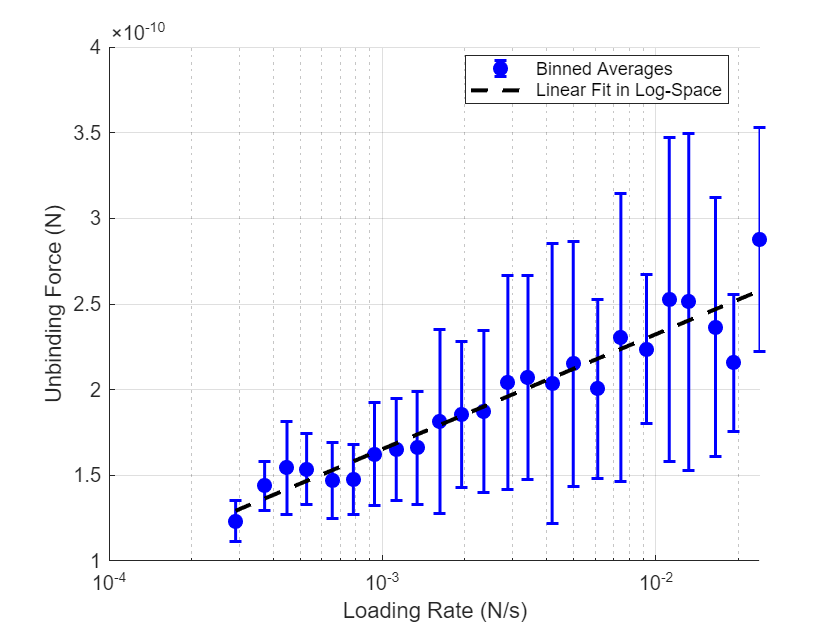

 
T  = 298; 
coeffs = polyfit(log(bin_avg_rate), bin_avg_force, 1);
A = coeffs(1);
B = coeffs(2);

% Generate a set of points for plotting the fit:
p_fit = linspace(min(bin_avg_rate), max(bin_avg_rate), 100);
F_fit = polyval(coeffs, log(p_fit));

% Create a plot
figure;
hold on;
set(gca, 'XScale','log');   % Plot with logarithmic x-axis

% Plot the original binned data with error bars (if available)
errorbar(bin_avg_rate, bin_avg_force, bin_std_force, 'bo', 'LineWidth',1.5, 'MarkerFaceColor','b');

% Plot the linear fit (in log space)
plot(p_fit, F_fit, 'k--', 'LineWidth', 2);

xlabel('Loading Rate (N/s)');
ylabel('Unbinding Force (N)');
legend('Binned Averages', 'Linear Fit in Log-Space','Location','Best');
grid on;
hold off;


% Display the fitted coefficients in the command window
fprintf('Fit result: F = %.2e * log(p) + %.2e\n', A, B);

Fit result: F = 2.91e-11 * log(p) + 3.66e-10


% Define physical constants
kB = 1.380649e-23;   % Boltzmann constant in J/K
          % Temperature in Kelvin

% Compute the reaction coordinate, x0, from the fit slope:
% A should approximate kB*T / x0, so:
x0_est = kB * T / A;

% Optionally, convert to Ångströms (1 Å = 1e-10 m)
x0_est_Angstrom = x0_est / 1e-10;
fprintf('Estimated reaction coordinate (x0): %.2f Å\n', x0_est_Angstrom);

Estimated reaction coordinate (x0): 1.41 Å


x0 =x0_est

x0 = 1.4136e-10

x0_save = x0;
tau_save = tau;
bin_avg_force_save = bin_avg_force;
save('results.mat','x0_save','tau_save','bin_avg_force_save')

Now use Kramers theory to determine the Free Energy difference. 

tau(F) = tau0(1-v F x0 /dG)^(1-1/v) x exp(-dG(1-[1-v F x0 / dG]^1/v) / kBT) 

Enter an initial guess for dG in units of kbT and the shape parameter v.


 
% ─── 1. Load your data (replace these with your actual variables) ───
% bin_avg_force: [n×1] forces in N
% tau           : [n×1] lifetimes in s

% Example (remove/comment out if you already have these):
% load('myData.mat','bin_avg_force','tau');

% ─── 2. Constants & dimensionless model ───
v   =0.5;              % shape parameter   
DGhat0 = 40;          % initial guess for dG in thermal energies
kBT = kB * T;            % thermal energy (J)

% p(1)=ΔĜ, p(2)=s0
kramersModel = @(p,F) ...
   p(2) .* ...
   ( max(1 - (v*x0.*F)./(kBT * p(1)), eps) ).^(1 - 1/v) ...
       .* exp( p(1) .* ( ( max(1 - (v*x0.*F)./(kBT * p(1)), eps) ).^(1/v) - 1 ) );



% ─── 3. Data-driven initial guess & bounds ───
s0_0   = max(tau);      % zero-force lifetime ~ your largest measured τ

p0 = [ DGhat0, s0_0 ];
%lb = [   0   ,    0  ];
%ub = [  50   ,   10  ];

% ─── 4. Sanity check: is the power‐law base ever ≤0? ───
base_vals = 1 - (v*x0.*bin_avg_force) ./ (kBT * p0(1));
fprintf('Min raw base = %.2e  → clamped to ≥ eps (%.2e)\n', ...
        min(base_vals), eps);

Min raw base = 8.76e-01  → clamped to ≥ eps (2.22e-16)


% If min(base_vals)<0, our clamping in the model kicks in and
% guarantees no complex outputs.

% ─── 5. Fit on the log‐scale (stabilizes the exponential) ───
opts = optimoptions('lsqcurvefit','Display','off');

% wrap so we minimize log(tau)−log(model)
fun_log = @(p,F) log( kramersModel(p,F) );
y       = log(tau);

p_fit = lsqcurvefit(fun_log, p0, bin_avg_force, y,[],[], opts);

DGhat_fit = p_fit(1);
s0_fit    = p_fit(2);

fprintf('\n→ Fitted ΔĜ = %.2f kBT\n', DGhat_fit);


→ Fitted ΔĜ = 9.30 kBT


fprintf('→ Fitted s0   = %.2e s\n',      s0_fit);

→ Fitted s0   = 2.86e-06 s


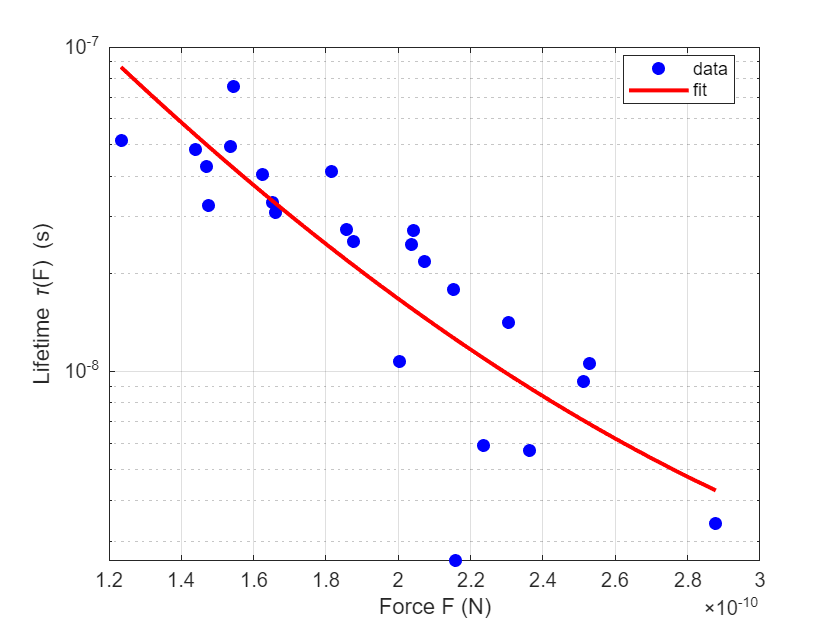


% ─── 6. Plot on semilog‐Y ───
F_plot = linspace(min(bin_avg_force), max(bin_avg_force), 200);
tau_fit = kramersModel(p_fit, F_plot);

figure;
semilogy(bin_avg_force, tau, 'bo','MarkerFaceColor','b');
hold on;
semilogy(F_plot,      tau_fit, 'r-','LineWidth',2);
xlabel('Force F (N)');
ylabel('Lifetime \tau(F) (s)');
legend('data','fit','Location','Best');
grid on;